% ========================================================
% === SCRIPT COMPLETO (Versione “pipeline + SVD_BC”) ===
% ========================================================
clear; clc; close all;
rng(0);

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------

this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI
%% ----------------------------------------------------------------
epochs       = 40;        
base_lr      = 0.01;      
lambda       = 1e-4;      
dropout_rate = 0.2;       
batch_size   = 32;        
patience     = 5;         

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');

>>> Caricamento dataset ORL...


tic;
load('dataset/volti_dataset_Yale.mat');  % A (m×n), labels
A      = double(A)/255;
labels = labels(:);
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.03 s



img_h = 112;
img_w = 92;
[m, n] = size(A);
num_classes = max(labels);

%% ----------------------------------------------------------------
%% 2.1) SVD: volto medio, centratura, SVD con svd_BC
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;

fprintf('>>> Calcolo volto medio...\n');  t0 = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t0));

   ok in 0.01 s



fprintf('>>> Centratura dati...\n');  t0 = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t0));

   ok in 0.00 s



fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n',tol,maxit);  t0 = tic;

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=1.58 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=1.51 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=1.43 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.46 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=160 ... iter=309 time=0.39 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=1.35 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=1.35 s
         [qr_eig] deflazione k=156 ... iter=765 time=1.00 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=1.18 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.41 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=1.30 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.22 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.21 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=1.28 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=1.24 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=1.17 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.23 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=1.14 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.15 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.09 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.76 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.69 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.67 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.70 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.05 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.60 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.59 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.57 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.59 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.28 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.56 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.48 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.42 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.39 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.41 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.41 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.29 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.33 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.10 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.27 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.31 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.26 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.25 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.21 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.23 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

fprintf('   completata in %.2f s\n', toc(t0));

   completata in 41.90 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% ----------------------------------------------------------------
%% 2.2) Visualizzazione mean face + prime 9 eigenfaces
%% ----------------------------------------------------------------
fprintf('>>> Visualizzo e salvo immagini SVD...\n');

>>> Visualizzo e salvo immagini SVD...


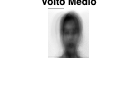

figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,112,92),[]);
title('Volto Medio');
saveas(gcf,fullfile(results_path,'volto_medio.png'));

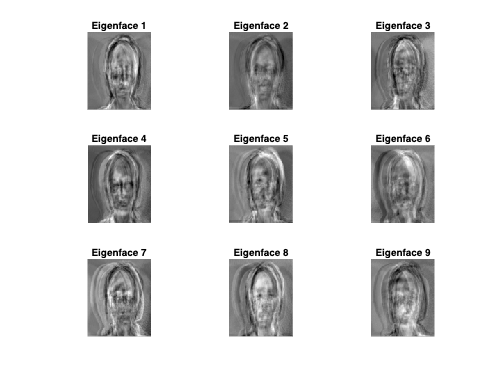


figure('Name','Prime 9 Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),112,92),[]);
    title(sprintf('Eigenface %d',i));
end
saveas(gcf,fullfile(results_path,'prime9_eigenfaces.png'));


%% ----------------------------------------------------------------
%% 3) PREPARAZIONE IMMAGINI (reshape) E SPLIT
%% ----------------------------------------------------------------
k = 150;

A_rec = U(:,1:k)*S(1:k,1:k)*V(:,1:k)' + mean_face;
imgs   = reshape(A_rec, img_h, img_w, []);

train_idx = [];  test_idx = [];
for s = 1:num_classes
    idx_s = find(labels==s);
    idx_s = idx_s(randperm(length(idx_s)));
    train_idx = [train_idx; idx_s(1:10)];
    test_idx  = [test_idx;  idx_s(11:end)];
end
imgs_train_base = imgs(:,:,train_idx);
y_train_base    = labels(train_idx)';
imgs_test       = imgs(:,:,test_idx);
y_test          = labels(test_idx)';

%% ----------------------------------------
%% 4) DATA AUGMENTATION SU TRAIN BASE (×12)
%% ----------------------------------------
[H, W, N_base] = size(imgs_train_base);  % 112×92×200
aug_per_image  = 12;                     % 1 originale + 11 augment
N_aug          = N_base * aug_per_image; % 200 × 12 = 2400

imgs_train_aug = zeros(H, W, N_aug);
y_train_aug    = zeros(1, N_aug);
cnt = 0;

for i = 1:N_base
    x   = imgs_train_base(:, :, i);    % [112×92]
    lbl = y_train_base(i);

    % 1) Originale
    cnt = cnt + 1;
    imgs_train_aug(:, :, cnt) = x;
    y_train_aug(cnt) = lbl;

    % 2) Traslazioni ±2 orizzontali, ±1 verticali (4)
    x_sh1 = imtranslate(x, [2, 0], 'FillValues', 0);
    x_sh2 = imtranslate(x, [-2, 0], 'FillValues', 0);
    x_sh3 = imtranslate(x, [0, 1], 'FillValues', 0);
    x_sh4 = imtranslate(x, [0, -1], 'FillValues', 0);
    for xx = {x_sh1, x_sh2, x_sh3, x_sh4}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 3) Rotazioni ±5°, ±10° (4)
    x_r5p  = imrotate(x,  5, 'bilinear', 'crop');
    x_r5n  = imrotate(x, -5, 'bilinear', 'crop');
    x_r10p = imrotate(x, 10, 'bilinear', 'crop');
    x_r10n = imrotate(x, -10,'bilinear', 'crop');
    for xx = {x_r5p, x_r5n, x_r10p, x_r10n}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 4) Zoom in +10%, Zoom out −10% (2)
    tmp_in  = imresize(x, 1.10);   x_zi = imresize(tmp_in, [H, W]);
    tmp_out = imresize(x, 0.90);   x_zo = imresize(tmp_out, [H, W]);
    for xx = {x_zi, x_zo}
        cnt = cnt + 1;
        imgs_train_aug(:, :, cnt) = xx{1};
        y_train_aug(cnt) = lbl;
    end

    % 5) Flip orizzontale (1)
    x_f = fliplr(x);
    cnt = cnt + 1;
    imgs_train_aug(:, :, cnt) = x_f;
    y_train_aug(cnt) = lbl;
end

assert(cnt == N_aug, 'Errore: il numero di esempi augmentato non corrisponde.');

%% --------------------------------------------------------
%% 5) CREAZIONE DEL VALIDATION SET (20% DI TRAIN AUMENTATO)
%% --------------------------------------------------------
perm_aug   = randperm(N_aug);
val_count  = round(0.20 * N_aug);          
val_idx_aug   = perm_aug(1:val_count);        % 480 (20% di 2400)
train_idx_aug = perm_aug(val_count+1:end);    % 1920 (80% di 2400)

imgs_train_eff = imgs_train_aug(:, :, train_idx_aug);   % [112×92×1920]
y_train_eff    = y_train_aug(train_idx_aug);            % [1×1920]
imgs_val       = imgs_train_aug(:, :, val_idx_aug);     % [112×92×480]
y_val          = y_train_aug(val_idx_aug);              % [1×480]

% One-hot per train e validation
Y_train_eff = zeros(num_classes, numel(y_train_eff));
for j = 1:numel(y_train_eff)
    Y_train_eff(y_train_eff(j), j) = 1;
end
Y_val = zeros(num_classes, numel(y_val));
for j = 1:numel(y_val)
    Y_val(y_val(j), j) = 1;
end

%% ---------------------------------------
%% 6) DEFINIZIONE ARCHITETTURA DELLA CNN
%% ---------------------------------------
% Rete con 3 layer conv + pool, poi fully-connected
f1 = 3;  n_f1 = 8;    % primo layer conv 3×3×8
f2 = 3;  n_f2 = 16;   % secondo layer conv 3×3×16
f3 = 3;  n_f3 = 8;    % terzo layer conv 3×3×8
pool = 2;

% Calcolo dimensioni feature map progressivamente:
conv1_h = img_h - f1 + 1;   % 110
conv1_w = img_w - f1 + 1;   % 90
pool1_h = floor(conv1_h / pool);  % 55
pool1_w = floor(conv1_w / pool);  % 45

conv2_h = pool1_h - f2 + 1; % 53
conv2_w = pool1_w - f2 + 1; % 43
pool2_h = floor(conv2_h / pool);  % 26
pool2_w = floor(conv2_w / pool);  % 21

conv3_h = pool2_h - f3 + 1; % 24
conv3_w = pool2_w - f3 + 1; % 19
pool3_h = floor(conv3_h / pool);  % 12
pool3_w = floor(conv3_w / pool);  % 9

% Dimensione finale del flatten:
fc_input_size = pool3_h * pool3_w * n_f3;  % 12×9×8 = 864
fprintf('[DEBUG arch] fc_input_size (layer 3) = %d\n', fc_input_size);

[DEBUG arch] fc_input_size (layer 3) = 864



% -------------------------------
% Inizializzazione pesi (He per conv, FC)
% -------------------------------
rng(0);
filters1 = randn(f1, f1, n_f1) * sqrt(2/(f1*f1*n_f1));   bias1 = zeros(n_f1, 1);
filters2 = randn(f2, f2, n_f2, n_f1) * sqrt(2/(f2*f2*n_f2)); bias2 = zeros(n_f2, 1);
filters3 = randn(f3, f3, n_f3, n_f2) * sqrt(2/(f3*f3*n_f3)); bias3 = zeros(n_f3, 1);

W_fc = randn(num_classes, fc_input_size) * sqrt(2 / fc_input_size);
b_fc = zeros(num_classes, 1);

%% ----------------------------------------------------
%% 7) TRAINING CON MINI‐BATCH, LR SCHEDULING,
%%    DROPOUT, L2, EARLY STOPPING SU VALIDATION
%% ----------------------------------------------------
loss_history   = zeros(1, epochs);
acc_history    = zeros(1, epochs);
val_loss_hist  = zeros(1, epochs);
val_acc_hist   = zeros(1, epochs);

best_val_acc       = 0;
best_params        = struct();
no_improve_counter = 0;

num_train_eff = size(imgs_train_eff, 3);
num_batches    = floor(num_train_eff / batch_size);

for epoch = 1:epochs
    % Aggiorno learning rate (decay a epocha 26)
    if epoch == 26
        lr = base_lr * 0.1;
    else
        lr = base_lr;
    end

    % Shuffle mini‐batch
    perm = randperm(num_train_eff);
    total_loss = 0;
    correct    = 0;

    for b = 1:num_batches
        idx_b = perm((b-1)*batch_size + (1:batch_size));
        Xb = imgs_train_eff(:, :, idx_b);    % [112×92×32]
        Yb = Y_train_eff(:, idx_b);          % [40×32]
        Nb = size(Xb, 3);

        % Inizializzo gradienti accumulati su batch
        dW1  = zeros(size(filters1)); db1  = zeros(size(bias1));
        dW2  = zeros(size(filters2)); db2  = zeros(size(bias2));
        dW3  = zeros(size(filters3)); db3  = zeros(size(bias3));
        dWfc = zeros(size(W_fc));      dbfc = zeros(size(b_fc));

        % ===================
        % === FORWARD BATCH ==
        % ===================
        for i_b = 1:Nb
            x      = Xb(:, :, i_b);
            y_true = Yb(:, i_b);

            % -- conv1 + ReLU + pool1 --
            [c1, cache1] = conv2d_forward(x, filters1, bias1);
            r1 = max(c1, 0);  % ReLU
            [p1, mask1] = maxpool2d_forward(r1, pool);

            % -- conv2 + ReLU + pool2 --
            [c2, cache2] = conv2d_forward_multi(p1, filters2, bias2);
            r2 = max(c2, 0);
            [p2, mask2] = maxpool2d_forward(r2, pool);

            % -- conv3 + ReLU + pool3 --
            [c3, cache3] = conv2d_forward_multi(p2, filters3, bias3);
            r3 = max(c3, 0);
            [p3, mask3] = maxpool2d_forward(r3, pool);

            % -- flatten e dropout --
            x_fc = reshape(p3, [], 1);           % [864×1]
            dropout_mask = (rand(size(x_fc)) > dropout_rate);
            x_fc_do = x_fc .* dropout_mask / (1 - dropout_rate);

            % -- fully‐connected + softmax --
            z_fc = W_fc * x_fc_do + b_fc;        % [40×1]
            z_fc = z_fc - max(z_fc);
            expz = exp(z_fc);
            y_pred = expz / sum(expz);

            % -- loss & accuracy --
            loss = -sum(y_true .* log(y_pred + 1e-12));
            total_loss = total_loss + loss;
            [~, pl] = max(y_pred); [~, tl] = max(y_true);
            if pl == tl
                correct = correct + 1;
            end

            % ======================
            % === BACKWARD BATCH ===
            % ======================
            dz_fc    = y_pred - y_true;             % [40×1]
            dWfc_b   = dz_fc * x_fc_do';            % [40×864]
            dbfc_b   = dz_fc;                       % [40×1]

            dx_fc_do = W_fc' * dz_fc;               % [864×1]
            dx_fc    = dx_fc_do .* dropout_mask / (1 - dropout_rate);

            dp3 = reshape(dx_fc, size(p3));         % [12×9×8]
            dr3 = maxpool2d_backward(dp3, mask3);   % Usa pool_h=floor(H/H_p), pool_w=floor(W/W_p)
            dc3 = dr3 .* (c3 > 0);
            [dp2, dW3_b, db3_b] = conv2d_backward_multi(p2, filters3, dc3, cache3);

            dr2 = maxpool2d_backward(dp2, mask2);
            dc2 = dr2 .* (c2 > 0);
            [dp1, dW2_b, db2_b] = conv2d_backward_multi(p1, filters2, dc2, cache2);

            dr1 = maxpool2d_backward(dp1, mask1);
            dc1 = dr1 .* (c1 > 0);
            [~, dW1_b, db1_b] = conv2d_backward(x, filters1, dc1, cache1);

            % Accumulo gradienti sul batch
            dWfc = dWfc + dWfc_b;   dbfc = dbfc + dbfc_b;
            dW3  = dW3  + dW3_b;    db3  = db3  + db3_b;
            dW2  = dW2  + dW2_b;    db2  = db2  + db2_b;
            dW1  = dW1  + dW1_b;    db1  = db1  + db1_b;
        end  % fine i_b su Nb

        % ============================
        % === UPDATE PESI (batch) ====
        % ============================
        filters1 = filters1 - lr * (dW1 / Nb + lambda * filters1);
        bias1    = bias1    - lr * (db1 / Nb);
        filters2 = filters2 - lr * (dW2 / Nb + lambda * filters2);
        bias2    = bias2    - lr * (db2 / Nb);
        filters3 = filters3 - lr * (dW3 / Nb + lambda * filters3);
        bias3    = bias3    - lr * (db3 / Nb);

        W_fc = W_fc - lr * (dWfc / Nb + lambda * W_fc);
        b_fc = b_fc - lr * (dbfc / Nb);
    end  % fine loop batches

    % ===============================
    % === CALCOLO STATISTICHE E STOPOGGING ===
    % ===============================
    loss_history(epoch) = total_loss / num_train_eff;
    acc_history(epoch)  = correct / num_train_eff * 100;

    % --- VALIDATION (solo forward) ---
    correct_val = 0;
    val_loss = 0;
    N_val = numel(y_val);

    for j = 1:N_val
        x      = imgs_val(:, :, j);
        y_true = Y_val(:, j);

        [c1, ~] = conv2d_forward(x, filters1, bias1); r1 = max(c1, 0);
        [p1, ~] = maxpool2d_forward(r1, pool);
        [c2, ~] = conv2d_forward_multi(p1, filters2, bias2); r2 = max(c2, 0);
        [p2, ~] = maxpool2d_forward(r2, pool);
        [c3, ~] = conv2d_forward_multi(p2, filters3, bias3); r3 = max(c3, 0);
        [p3, ~] = maxpool2d_forward(r3, pool);

        x_fc = reshape(p3, [], 1);
        z_fc = W_fc * x_fc + b_fc;
        z_fc = z_fc - max(z_fc);
        expz = exp(z_fc);
        y_pred = expz / sum(expz);

        loss_v = -sum(y_true .* log(y_pred + 1e-12));
        val_loss = val_loss + loss_v;
        [~, pl] = max(y_pred); [~, tl] = max(y_true);
        if pl == tl
            correct_val = correct_val + 1;
        end
    end

    val_loss_hist(epoch) = val_loss / N_val;
    val_acc_hist(epoch)  = correct_val / N_val * 100;

    fprintf('[EPOCA %2d] Train Loss=%.4f Acc=%.2f%% | Val Loss=%.4f Acc=%.2f%%\n', ...
            epoch, loss_history(epoch), acc_history(epoch), val_loss_hist(epoch), val_acc_hist(epoch));

    % Early stopping: se validazione non migliora per 'patience' epoche
    if val_acc_hist(epoch) > best_val_acc
        best_val_acc = val_acc_hist(epoch);
        best_params.filters1 = filters1;
        best_params.bias1    = bias1;
        best_params.filters2 = filters2;
        best_params.bias2    = bias2;
        best_params.filters3 = filters3;
        best_params.bias3    = bias3;
        best_params.W_fc     = W_fc;
        best_params.b_fc     = b_fc;
        best_params.pool     = pool;
        no_improve_counter   = 0;
    else
        no_improve_counter = no_improve_counter + 1;
        if no_improve_counter >= patience
            fprintf('Early stopping: non migliora validazione da %d epoche!\n', patience);
            break;
        end
    end
end  % fine epoche

[EPOCA  1] Train Loss=2.7084 Acc=6.94% | Val Loss=2.7093 Acc=5.28%
[EPOCA  2] Train Loss=2.7080 Acc=5.90% | Val Loss=2.7108 Acc=5.83%
[EPOCA  3] Train Loss=2.7081 Acc=6.88% | Val Loss=2.7109 Acc=5.83%
[EPOCA  4] Train Loss=2.7077 Acc=7.78% | Val Loss=2.7117 Acc=5.83%
[EPOCA  5] Train Loss=2.7078 Acc=6.60% | Val Loss=2.7124 Acc=5.83%
[EPOCA  6] Train Loss=2.7077 Acc=6.04% | Val Loss=2.7129 Acc=5.28%
[EPOCA  7] Train Loss=2.7068 Acc=8.54% | Val Loss=2.7146 Acc=5.28%


Early stopping: non migliora validazione da 5 epoche!



% Se ci siamo fermati prima di 'epochs', aggiorno epoch effettive:
actual_epochs = epoch;

%% ----------------------------
%% 8) VALUTAZIONE SUL TEST SET
%% ----------------------------
fprintf('>>> Valutazione modello su TEST SET...\n');

>>> Valutazione modello su TEST SET...


filters1 = best_params.filters1; bias1 = best_params.bias1;
filters2 = best_params.filters2; bias2 = best_params.bias2;
filters3 = best_params.filters3; bias3 = best_params.bias3;
W_fc     = best_params.W_fc;     b_fc = best_params.b_fc;
pool     = best_params.pool;

correct_test = 0;
num_test = size(imgs_test, 3);

for i = 1:num_test
    x = imgs_test(:, :, i);

    [c1, ~] = conv2d_forward(x, filters1, bias1);  r1 = max(c1, 0);
    [p1, ~] = maxpool2d_forward(r1, pool);
    [c2, ~] = conv2d_forward_multi(p1, filters2, bias2); r2 = max(c2, 0);
    [p2, ~] = maxpool2d_forward(r2, pool);
    [c3, ~] = conv2d_forward_multi(p2, filters3, bias3); r3 = max(c3, 0);
    [p3, ~] = maxpool2d_forward(r3, pool);

    x_fc = reshape(p3, [], 1);
    z_fc = W_fc * x_fc + b_fc;
    z_fc = z_fc - max(z_fc);
    expz = exp(z_fc);
    y_pred = expz / sum(expz);

    [~, pl] = max(y_pred);
    if pl == y_test(i)
        correct_test = correct_test + 1;
    end
end

acc_test = correct_test / num_test * 100;
fprintf('Accuracy finale sul TEST SET: %.2f%%\n', acc_test);

Accuracy finale sul TEST SET: 6.67%


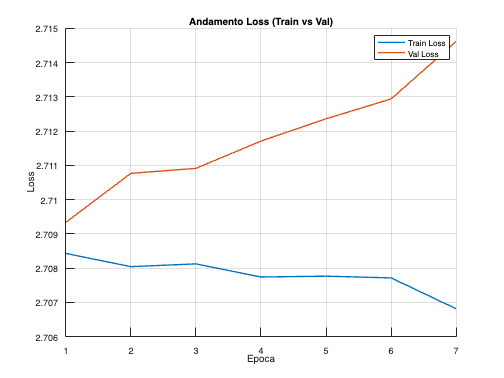


%% ------------------------------
%% 9) PLOTTAGGIO STATISTICHE
%% ------------------------------
figure; hold on;
plot(1:actual_epochs, loss_history(1:actual_epochs), 'LineWidth', 1.5);
plot(1:actual_epochs, val_loss_hist(1:actual_epochs), 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Loss');
legend('Train Loss', 'Val Loss');
title('Andamento Loss (Train vs Val)');
grid on;

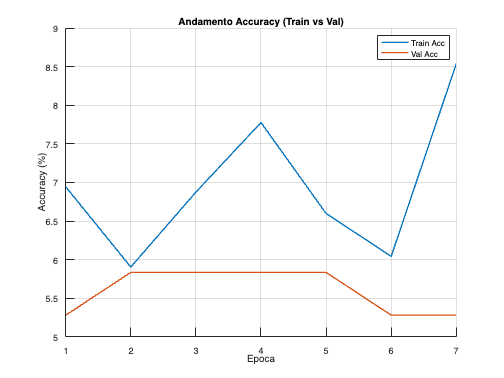


figure; hold on;
plot(1:actual_epochs, acc_history(1:actual_epochs), 'LineWidth', 1.5);
plot(1:actual_epochs, val_acc_hist(1:actual_epochs), 'LineWidth', 1.5);
xlabel('Epoca'); ylabel('Accuracy (%)');
legend('Train Acc', 'Val Acc');
title('Andamento Accuracy (Train vs Val)');
grid on;